# 3D Drone Control

***Thöni Andreas, Peer Samuel**** (MA-MECH-25-VZ)*

This project implemented the mathematical model of a drone in 3D-space and implemented a waypoint following system using a simple LQR-controller.

Run this file before running the Simulink model *"DroneControlSimulink"*. After running the simulation, run *"DroneControlPlot.m"* for an animated plot of the drone and the waypoints. *"DataInsp_drone.mldatx"* is the DataInspector-session that can also be used to view the simulation results in graph-form.

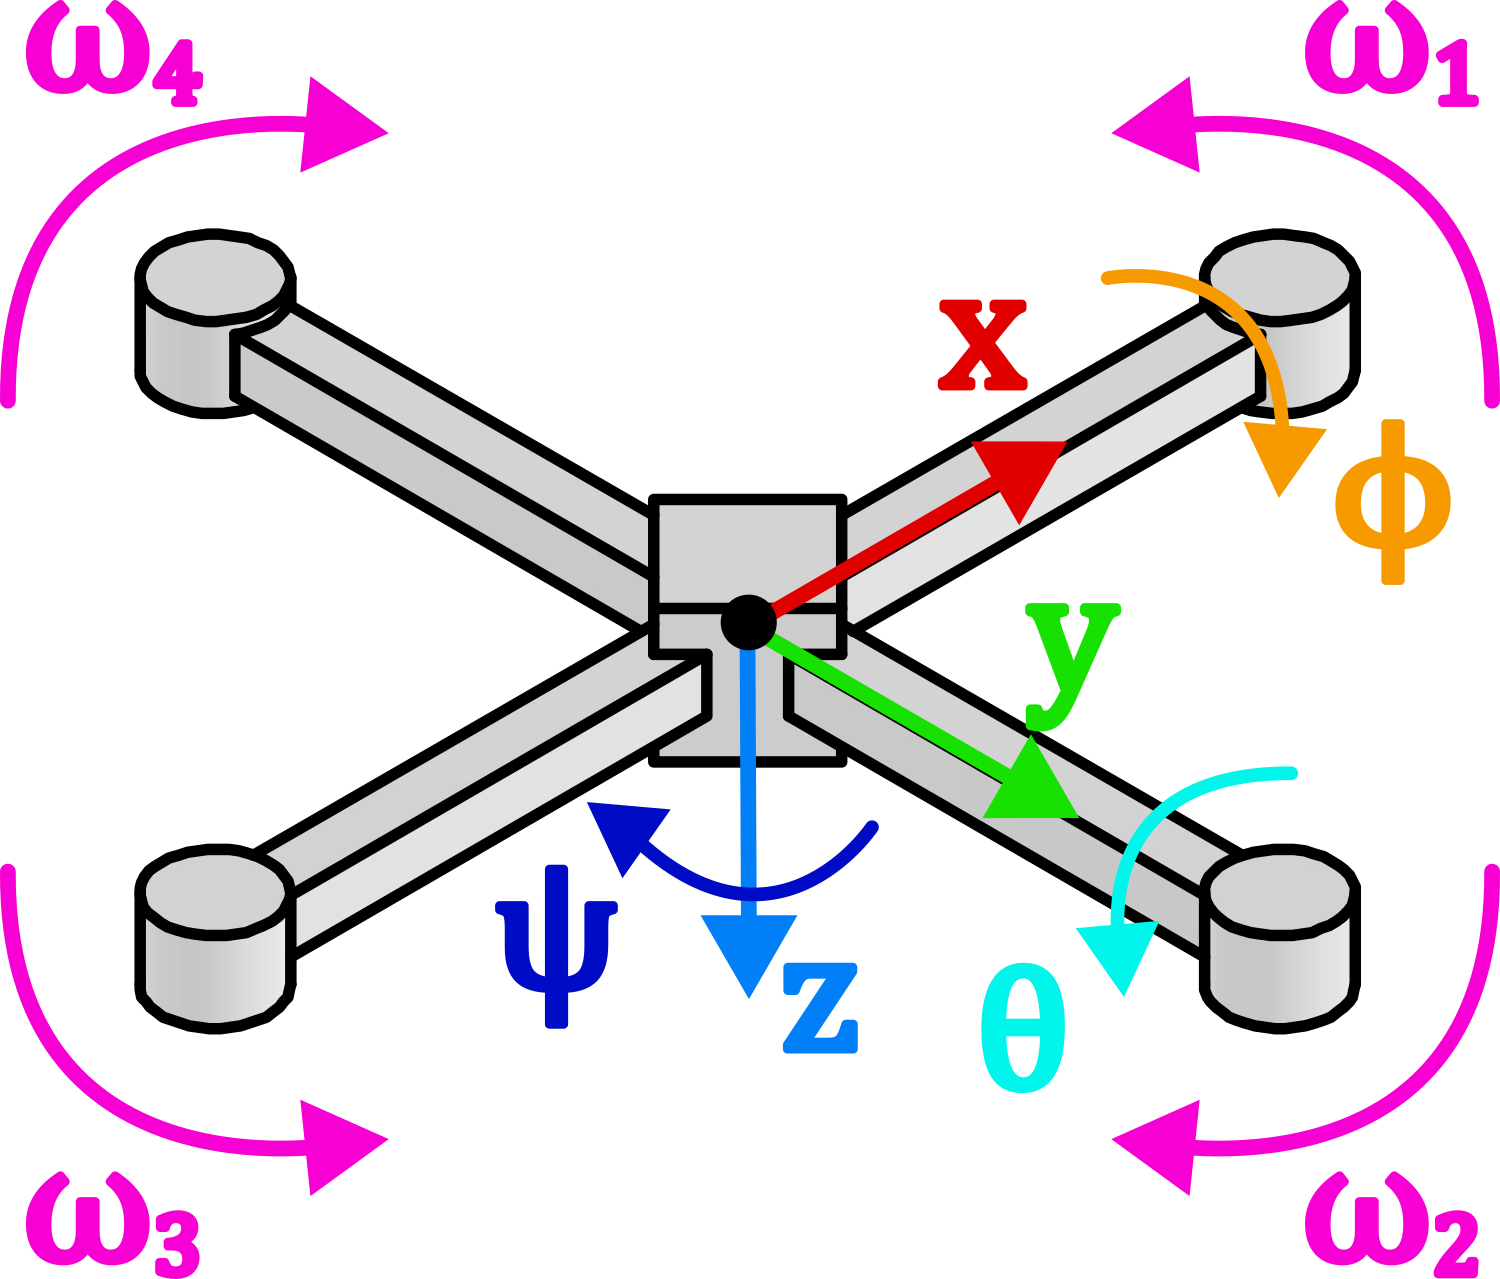

clear all

The mathematical modelling of the system involves a lot of coordinate transforms in the form of rotation matrices and are not included in this live-script. They are however, explained a little bit more detailed in comments of the function block in the Simulink file as well as in *"presentation.pptx"*.

## Parameters

This section defines parameters that are needed for running the mathematical model in Simulink. They include the mass $m$, the distance from the center of gravity to a rotor $l$, the inertia tensor $\underset{\sim}{J}$, propeller coefficients and limits on the angular velocities of the rotors.

### General Parameters

m = 0.568;          % kg
g = 9.81;           % m/s^2
l = 0.2;            % m

### Inertia-Tensor of Drone & Inertia of motor

As the drone is symmetric and the rotations are around the principal axes, only the principal moments of inertia are needed, and $J_\mathrm{xx}$ and $J_\mathrm{yy}$ are of the same size.

J_xx = 5144.434e-6;     % kgm^2
J_yy = 5144.434e-6;     % kgm^2
J_zz = 10289.036e-6;    % kgm^2

% Inertia motor
J_r = 15e-6;           % kgm^2

### Propeller Parameters

The thrust generated by the propellers are calculated with $T_\mathrm{i} = K\,\Omega_\mathrm{i}^2$, where $K$ is either the *thrust factor *$b$ or the *drag factor* $d$, depending on the desired orientation of the quadrotor.

C_T = 0.121;            % thrust coeffieicnt
C_p = 0.0495;           % power coefficient
rho_A = 1.255;          % air density
D = 0.15;               % blade diameter

b = C_T*rho_A*D^4;      % thrust factor
d = C_p*rho_A*D^5;      % drag factor

rpm_max = 8000;
w_max = rpm_max/60*2*pi; % maximum angular velocity propeller
w_min = 0;               % minimum angular velocity propeller

### Drone Drag Coefficients

These are the coefficients which would describe how wind or similar effects would affect the drone in each axis. In this project, they were disregarded and set to zero.

K_dx = 0;
K_dy = 0;
K_dz = 0;

### Initial conditions

Initial position, angle, etc. of the drone. The sequence is $[x, y, z, \dot{x}, \dot{y}, \dot{z}, \Phi, ¸\Theta, \Psi, p, q, r]$.

X0 = zeros(12,1);

### Motors

This is a simple PT1 system to simulate motors, with no $k_\omega$, only $\tau$, derived from $\dot{\omega}=\frac{1}{\tau}\,\omega_\mathrm{cmd}-\frac{1}{\tau}\,\omega$.

tau = 0.05;
ss_mot = ss([-1/tau], [1/tau], [1], [0]);

### Matrix to Convert Forces and Torques to $\omega$'s

The controller outputs forces and torques, which should be applied to the drone. To receive the necessary angular velocities out of these, the following matrix is used.

omega_inv = [1/(4*b),     0,      1/(2*b),   1/(4*d);
             1/(4*b), -1/(2*b),      0,     -1/(4*d);
             1/(4*b),     0,     -1/(2*b),   1/(4*d);
             1/(4*b),  1/(2*b),      0,     -1/(4*d)];

## Waypoint definition

Definition of the points that the drone should fly through during the simulation.

traj_times = [0, 5, 10, 15, 20];

traj_points = [
    2,-1,-1,0,0,0,0,0,pi/4,0,0,0;
    0,-2,-2,0,0,0,0,0,0,0,0,0;
    1,1,-1,0,0,0,0,0,0,0,0,0;
    -2,2,1,0,0,0,0,0,-pi/4,0,0,0;
    -2,-1,1,0,0,0,0,0,0,0,0,0;
    ];

## Control Design

The linearized version of the mathematical model is saved in *"linearized_model.mat"* which is the result of running* "DroneControlLinearization.mlx"*. It is loaded and used for control design in this section. The linearization was done around the hovering point.

### System matrices

The system matrices and the state-space model are defined in this section. Also the controllability is checked for.

T = 0.05;

% Convert symbolic A and B to numeric
load("linearized_model.mat")
A_c = double(subs(A_lin, [K_dx_sym K_dy_sym K_dz_sym m_sym g_sym l_sym I_xx_sym I_yy_sym I_zz_sym], ...
                  [K_dx K_dy K_dz m g l J_xx J_yy J_zz]))

A_c =          0         0         0    1.0000         0         0         0         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0
         0         0         0         0         0         0         0   -9.8100         0         0         0         0
         0         0         0         0         0         0    9.8100         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0    1.0000         0         0
         0         0         0         0         0         0         0         0         0         0    1.0000         0
         0         0      

B_c = double(subs(B_lin, [m_sym l_sym I_xx_sym I_yy_sym I_zz_sym], ...
                  [m l J_xx J_yy J_zz]))

B_c =          0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
   -1.7606         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0   38.8770         0         0
         0         0   38.8770         0
         0         0         0   97.1908


C_c = eye(12);
D_c = 0;

% controllability
M_c = ctrb(A_c, B_c);
rank(M_c)

ans = 12


% state space
sys_c = ss(A_c, B_c, C_c, D_c);
I = eye(size(A_c));

### LQR

Linear quadratic regulator using the linearized system.

Q = I;
R = 1;
K_LQR = lqr(sys_c, 1*Q, R);

### MPC

Attempt at setting up MPC which ended up not working correctly, unfortunately.

pred_h = 30;
ctrl_h = 5;

mpcobj = mpc(sys_c, T, pred_h, ctrl_h);

-->"Weights.ManipulatedVariables" is empty. Assuming default 0.00000.
-->"Weights.ManipulatedVariablesRate" is empty. Assuming default 0.10000.
-->"Weights.OutputVariables" is empty. Assuming default 1.00000.
   for output(s) y1 y2 y3 y4 and zero weight for output(s) y5 y6 y7 y8 y9 y10 y11 y12 


mpcobj.Model.Nominal.U = [m*g 0 0 0];
mpcobj.Model.Nominal.X = zeros(1, 12);
mpcobj.Model.Nominal.Y = zeros(1, 12);
mpcobj.Weights.OutputVariables = [10, 10, 10, 0, 0, 0, 0, 0, 0, 0, 0, 0]; % x y z important, rest egal
mpcobj

 
MPC object (created on 13-Jul-2026 07:31:07):
---------------------------------------------
Sampling time:      0.05 (seconds)
Prediction Horizon: 30
Control Horizon:    5

Plant Model:        
                                      --------------
      4  manipulated variable(s)   -->| 12 states  |
                                      |            |--> 12 measured output(s)
      0  measured disturbance(s)   -->|  4 inputs  |
                                      |            |-->  0 unmeasured output(s)
      0  unmeasured disturbance(s) -->| 12 outputs |
                                      --------------
Disturbance and Noise Models:
        Output disturbance model: default (type "getoutdist(mpcobj)" for details)
         Measurement noise model: default (unity gain after scaling)

Weights:
        ManipulatedVariables: [0 0 0 0]
    ManipulatedVariablesRate: [0.1000 0.1000 0.1000 0.1000]
             OutputVariables: [10 10 10 0 0 0 0 0 0 0 0 0]
                         ECR: 1

## Sources

These are the two main sources that have been used to support the mathematical modeling of the drone.

[https://wilselby.com/research/arducopter/modeling/](https://wilselby.com/research/arducopter/modeling/) (accessed 16.07.2026)

[https://www.open-access.bcu.ac.uk/11859/1/Mathematical%20%26%20Physical%20Modelling%20of%20a%20Quadrotor%20UAV.pdf](https://www.open-access.bcu.ac.uk/11859/1/Mathematical%20%26%20Physical%20Modelling%20of%20a%20Quadrotor%20UAV.pdf) (accessed 16.07.2026)